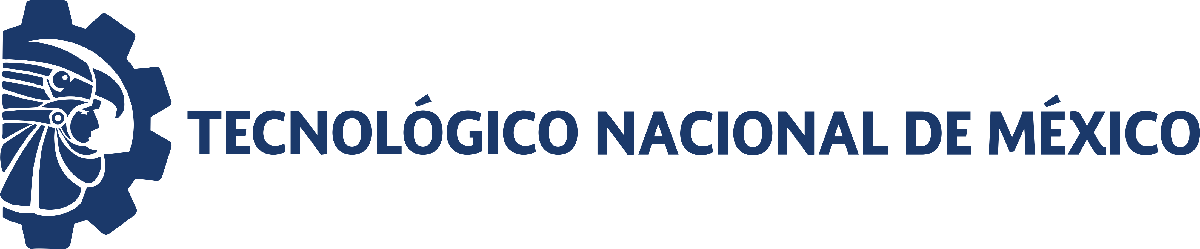                                 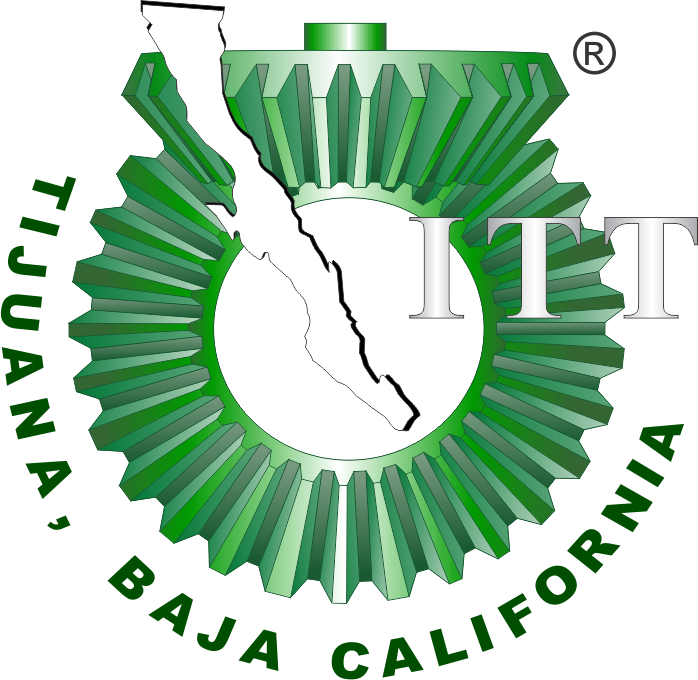

# Práctica dos:  Modelo y control del sistema cardiovascular mediante el modelo Windkessel

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

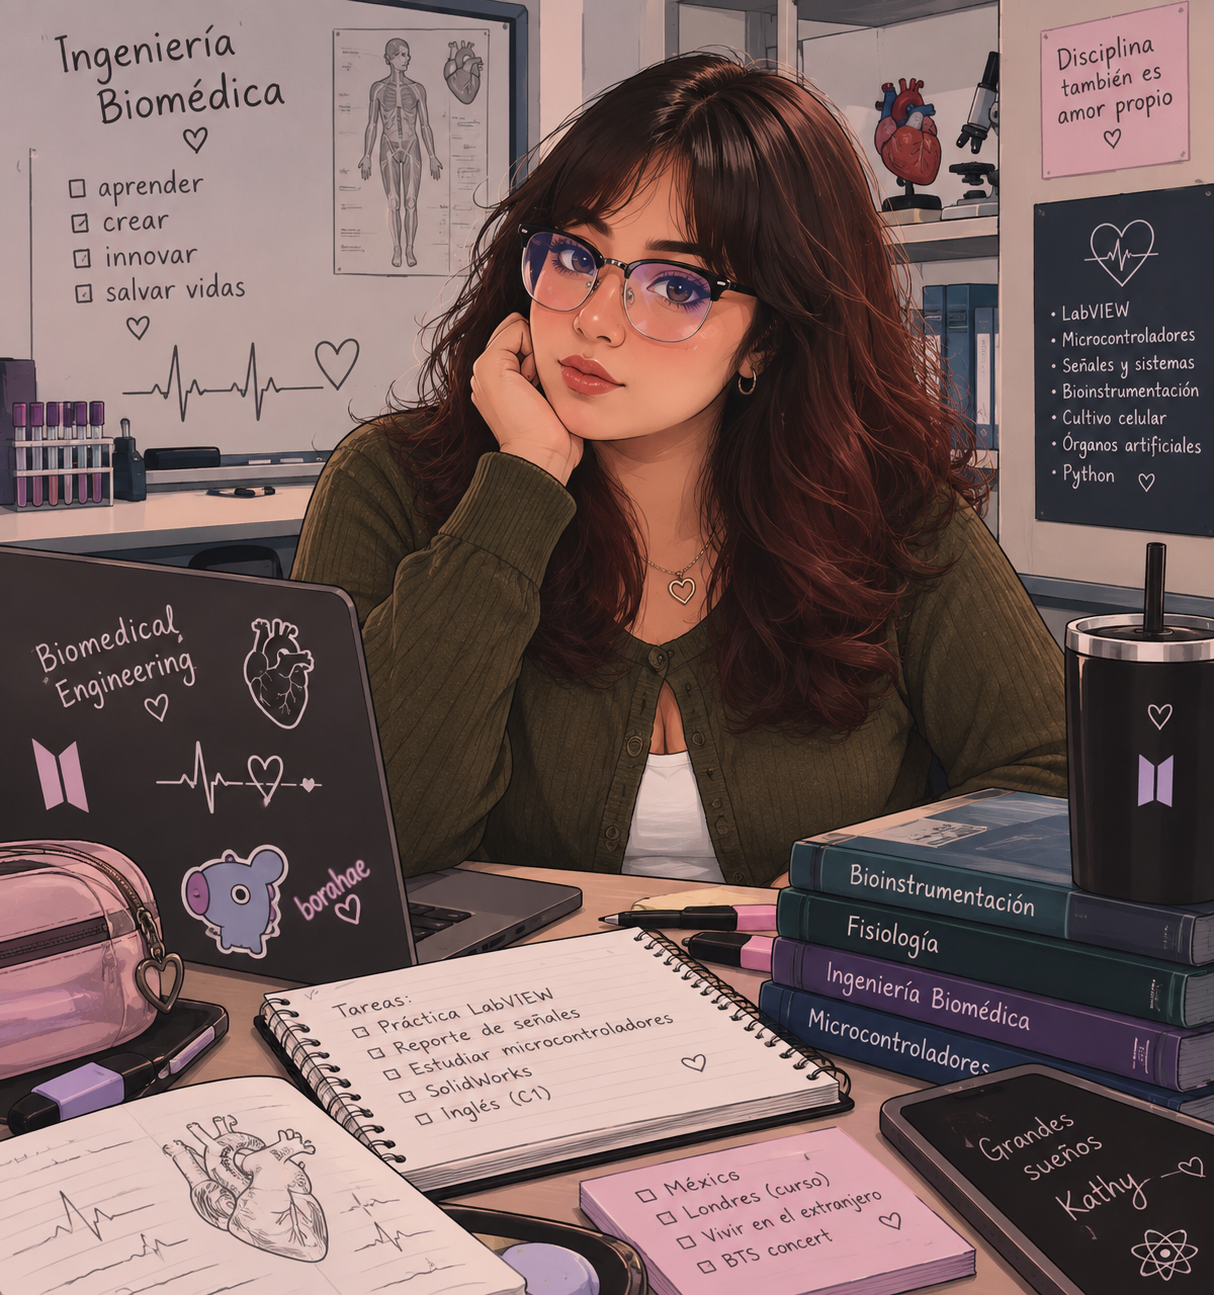

Nombre del alumno: Katherine Coria Camacho

Número de control: 23212189

Correo institucional: l23212189**@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning('off','all')
open_system('sistema3')
close_system('sistema3/Scope',0);
parameters.StopTime= '15'

parameters = struct with fields:
    StopTime: '15'


parameters.Solver = 'ode15s';
parameters.MaxStep = ' 1e-2';
x = sim('sistema3',parameters);

t_data = (0:0.1:15)';
t = (0:0.001:15)';
Pa = interp1(t_data,x.Pa,t,'previous');
writematrix(Pa,'signal.xlsx');

## Respuesta Lazo abierto

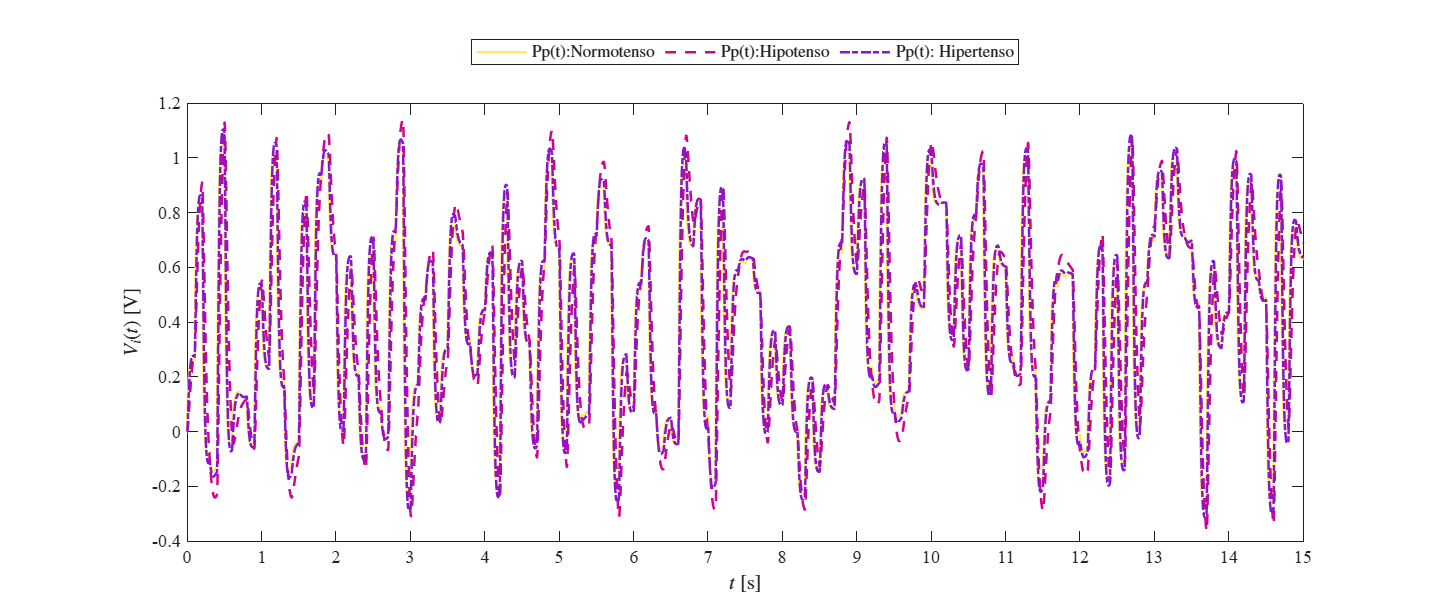


plotsignals(x.t, x.PpN, x.PpL, x.PpH, ...
    'Normotenso', ...
    {'Pp(t):Normotenso', ...
    'Pp(t):Hipotenso', ...
    'Pp(t): Hipertenso'});

## Respuesta Hipotenso

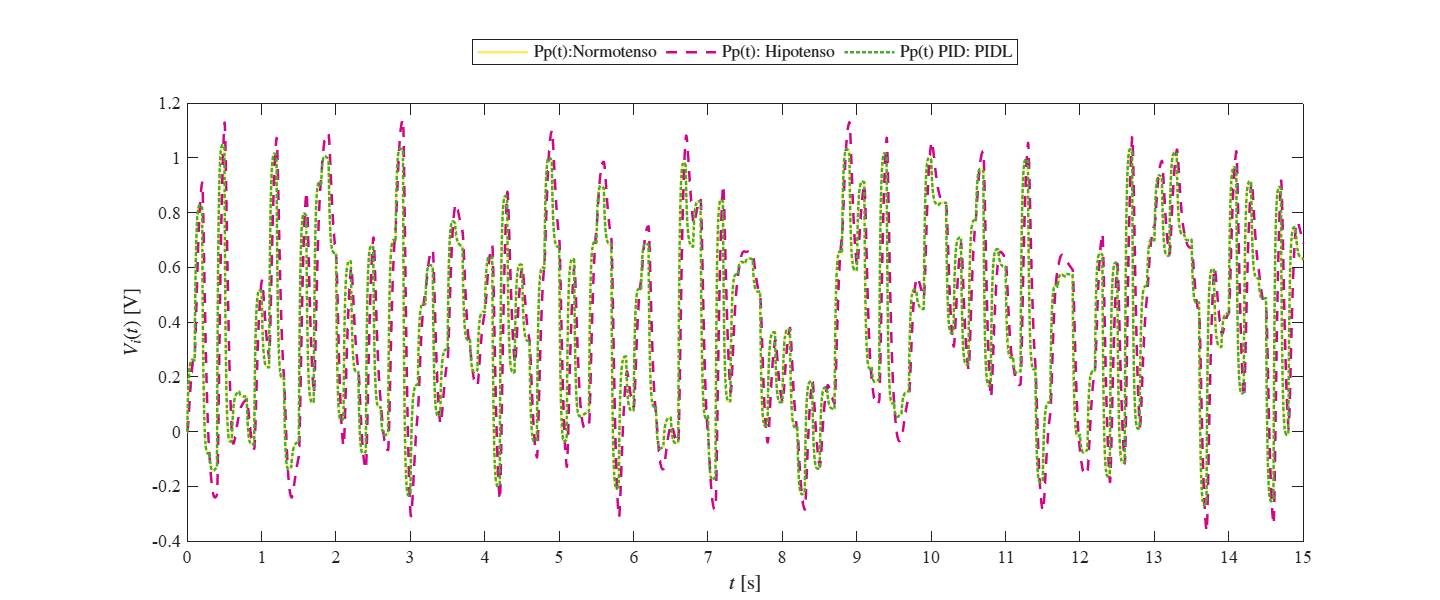

plotsignals(x.t, x.PpN, x.PpL, x.PIDL, ...
    'Hipotenso', ...
    {'Pp(t):Normotenso', ...
    'Pp(t): Hipotenso', ...
    'Pp(t) PID: PIDL'});

## Respuesta Hipertenso

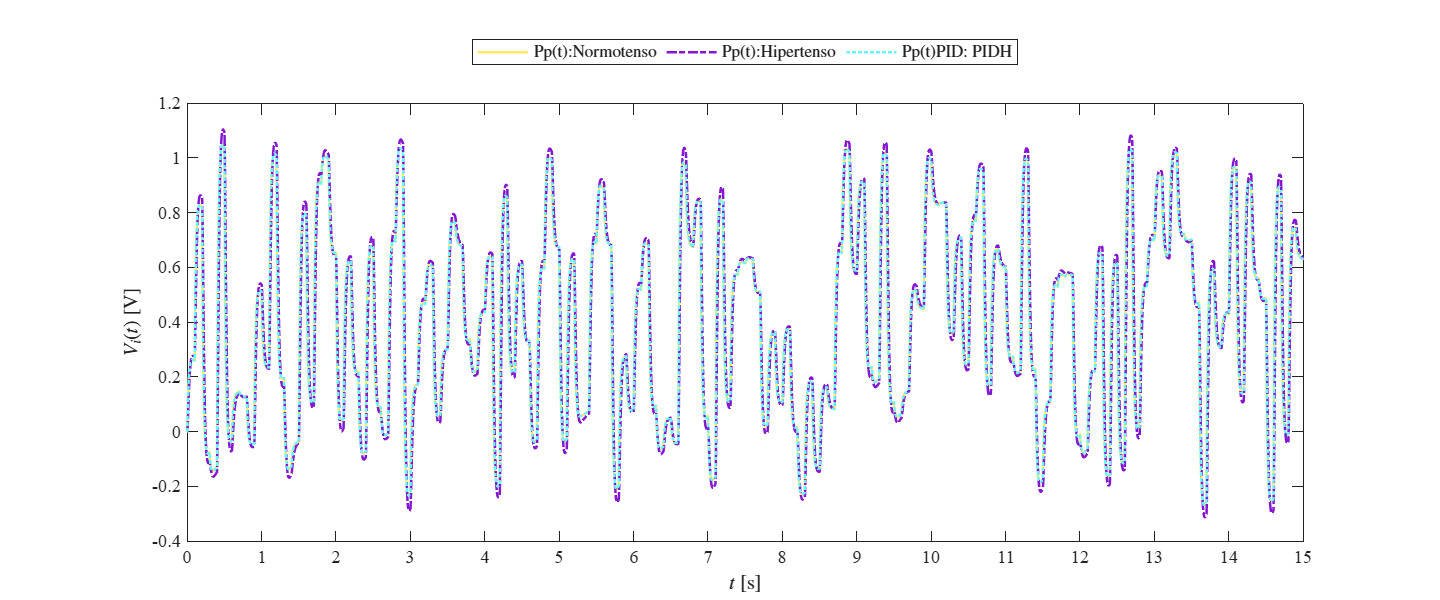

plotsignals(x.t, x.PpN, x.PpH, x.PIDH, ...
    'Hipertenso', ...
    {'Pp(t):Normotenso', ...
    'Pp(t):Hipertenso ', ...
    'Pp(t)PID: PIDH'});

## Función: Respuestas de la simulación


function plotsignals(t, y1, y2, y3, nombre, etiquetas)
t  = t(:);
y1 = y1(:);
y2 = y2(:);
y3 = y3(:);

% Colores Simulink
cN    = [1.00, 0.91, 0.39]; % Normotenso
cL    = [0.82, 0.02, 0.55]; % Hipotenso
cPIDL = [0.28, 0.67, 0.20]; % PID hipotenso
cH    = [0.52, 0.09, 0.82]; % Hipertenso
cPIDH = [0.42, 0.96, 1.00]; % PID hipertenso

% Seleccionar colores y estilos
switch nombre

    case 'Normotenso'
        colores = [cN; cL; cH];
        estilos = {'-', '--', '-.'};

    case 'Hipotenso'
        colores = [cN; cL; cPIDL];
        estilos = {'-', '--', ':'};

    case 'Hipertenso'
        colores = [cN; cH; cPIDH];
        estilos = {'-', '-.', ':'};

end

% Crear figura
figure('Color','w', ...
    'Units','inches', ...
    'Position',[1,1,12,5]);

set(gca,'FontName','Times New Roman','FontSize',11);
hold on;
grid off;
box on;

% Graficar las señales
for k = 1:3
    datos = {y1, y2, y3};

    plot(t, datos{k}, ...
        'Color', colores(k,:), ...
        'LineStyle', estilos{k}, ...
        'LineWidth', 1.5);
end

% Leyenda
L = legend(etiquetas);
set(L,'Interpreter','latex', ...
    'Location','northoutside', ...
    'Orientation','horizontal');

% Ejes
xlabel('$t$ [s]','Interpreter','latex');
ylabel('$V_i(t)$ [V]','Interpreter','latex');

xlim([0 15]);
xticks(0:1:15);

% Guardar figura
exportgraphics(gcf, ...
    [nombre,'_matlab.pdf'], ...
    'ContentType','vector');

hold off;

end

